load 'sshmean.mat'

**Figure 1. Regional Mean Sea Surface Height **

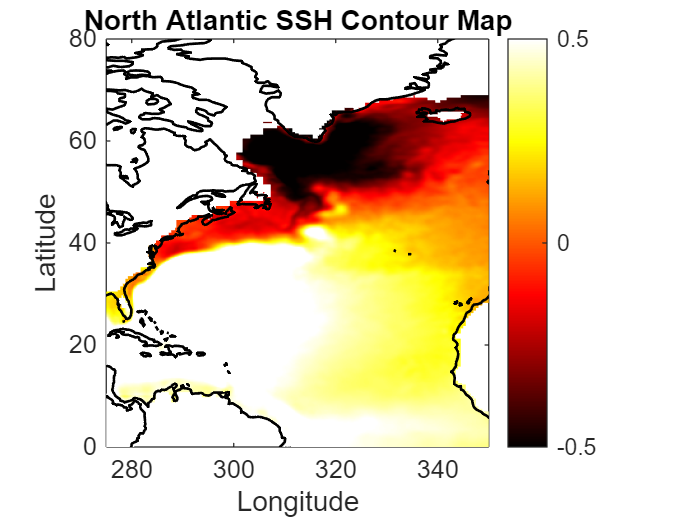

clf
pcolor(lon, lat, ssh)
shading flat
title('North Atlantic SSH Contour Map')
colorbar()
colormap('hot')
daspect([1, cosd(mean(lat)), 1])
xlabel('Longitude')
ylabel('Latitude')
xlim([275,350])
ylim([0,80])
plotmap()
caxis([-0.5,0.5])

Calculating Zonal Geostrophic Velocity 


$$u=-\frac{g}{f}\frac{d\left(\mathrm{ssh}\right)}{\mathrm{dy}}$$


%defining variables
g = 10

g = 10

omega = 2*pi/86400

omega = 7.2722e-05

f = 2 * omega * sind(lat);

%distance in degrees between two latitudes 
lat(2)-lat(1)

ans = 0.2500

%distance in meters between two latitudes
dy = (lat(2) - lat(1))/360 * (2*pi*6400000)

dy = 2.7925e+04


%creating empty SSH gradient and velocity matrices for the loop
dssh=zeros(size(ssh));
ugeo=zeros(size(ssh));

%loop to create a gradient(dssh) of change in sea surface height at each
%lat and lon point, and then calculating the eastward geostorphic velocity
%at each point from that gradient 
for x=1:length(lon)
  for y=1:length(lat)-1 %note the -1 here. Why is that? What happens if you don't put a -1 here?
    dssh(y,x) = ssh(y+1,x)-ssh(y,x);
    ugeo(y,x) = -g/f(y)*dssh(y,x)/dy;
  end;
end;
;

**Figure 2. Regional Zonal Geostrophic Velocity **

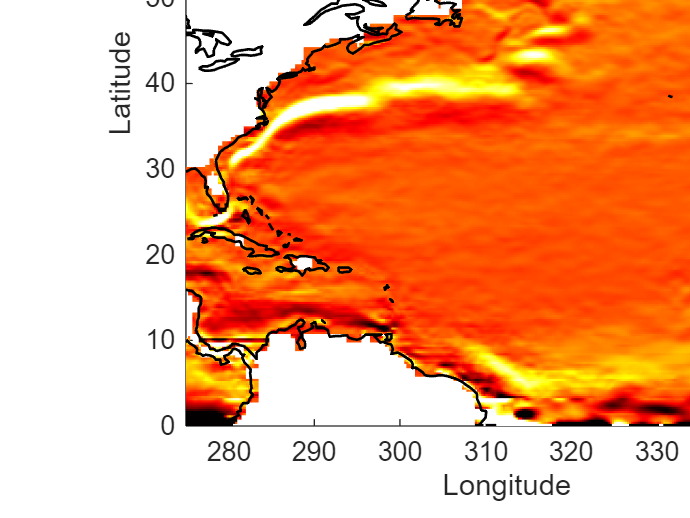

clf
pcolor(lon, lat, ugeo)
shading flat
colorbar()
colormap("hot")
caxis([-0.5,0.5])
title('North Atlantic Zonal Geostrophic Velocity')
xlabel('Longitude')
ylabel('Latitude')
plotmap()
daspect([1, cosd(mean(lat)), 1])
xlim([275;350])
ylim([0,80])

Calculating Meridional Geostrophic Velocity 


$$v=\frac{g}{f}\frac{d\left(\textrm{ssh}\right)}{\textrm{dx}}$$


%distance in meters between two longitude points 
dx = (lon(2)-lon(1))*2*pi*6400000/360*cosd(lat(y));

%creating empty matrices for gradient of sea surface height and meridional
%geostrophic velocities 
dssh=zeros(size(ssh));
vgeo=zeros(size(ssh));

%%loop to create a gradient(dssh) of change in sea surface height at each
%lat and lon point, and then calculating the eastward geostorphic velocity
%at each point from that gradient 
for y=1:length(lat)
  for x=1:length(lon)-1   %note the -1 is now here. Why?
    dx = (lon(2)-lon(1))*110*1000*cosd(lat(y));
    dssh(y,x) = ssh(y,x+1)-ssh(y,x);
    vgeo(y,x) = g/f(y)*dssh(y,x)/dx; % ... [fill in the blanks (take care to get the sign right)]
  end;
end;

 Global SSH and Geostrophic Velocities

**Figure 3. Regional SSH and Zonal/Meridional Geostrophic Velocity Vectors**

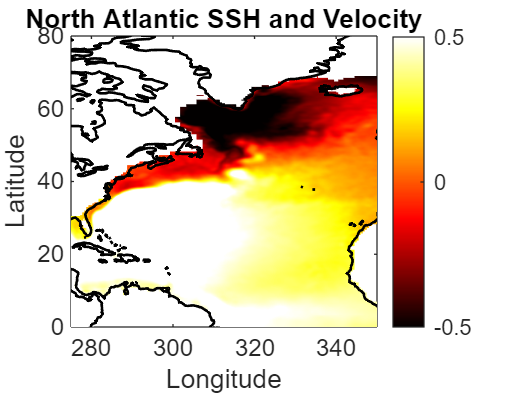

clf
di=10;
pcolor(lon,lat,ssh)
shading flat
plotmap()
colorbar()
colormap('hot')
title('North Atlantic SSH and Velocity')
xlabel('Longitude')
ylabel('Latitude')
caxis([-0.5,0.5])
%daspect([1, cosd(mean(lat)), 1])
hold on;
quiver(lon(1:di:end),lat(1:di:end),ugeo(1:di:end,1:di:end),vgeo(1:di:end,1:di:end),3)
xlim([275, 350])
ylim([0,80])

Notes:

Western boundary currents are huge drivers in ocean basins. They are responsible for large scale phenomena such as transporting heat over ocean basins, moving larvae up coasts, and on a smaller scale, a creater of eddies altering local productivity levels. These currents are geostrophic, driven by a pressure force created in part by sea surface height and the coriolis force. Taking the North Atlantic ocean basin as a case study, one can see a slight sea surface height difference in the center of the basin (Figure 1). This also contributes to the meridional gradient in sea surface height from about 30 degrees N to 60 degrees N as shown by the quick change in high to low sea surface height in Figure 1. This large SSH gradient creates a corresponding meridional pressure gradient force. However, looking at Figure 2 we see a body of water with a positive, eastward velocity in the basin, not flowing northwards following the pressure gradient. This is because the Coriolis force is balancing out the pressure gradient force diverting the water 90 degrees to the right in the northern hemisphere causing the geostrophic, western boundary current to flow eastwards. Overlaying the current's velocities vectors over sea surface height (Figure 3) this shows water moving northward quickly (Florida Current) initially along the pressure gradient (high SSH to low SSH) and then eastwards around 40 degrees N as it gets diverted by the Coriolis Force (Gulfstream Current).  These currents then transport heat, nutrients, larvae, etc up the North American coast and across the North Atlantic to Europe which can have large impacts on the physics, biology, and also climate.